# Image processing fundamentals

This notebook is based on Chapter 2 Digital Image Processing using MATLAB

## Reading and showing images

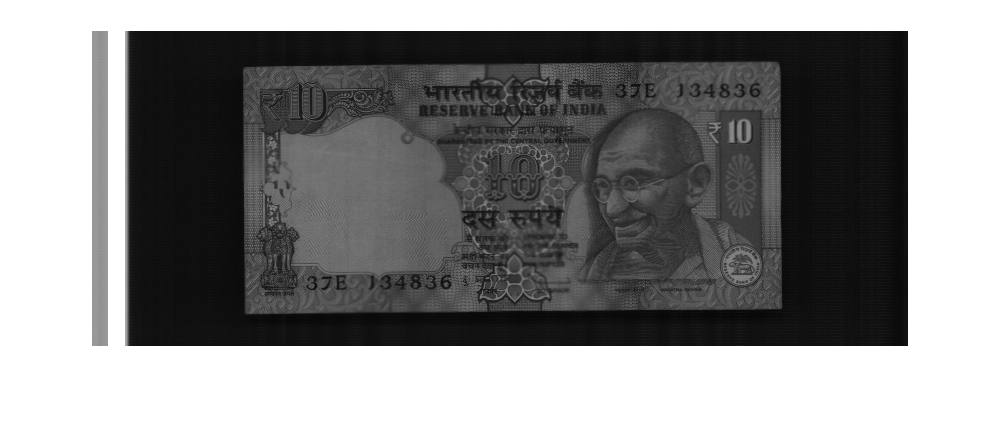

I = imread('image.tif');
I1 = imread('image', 'tif'); % has same effect as above

figure; imshow(I); % show the image using the default values 0 ... 255 (0 is black , 255 is white)

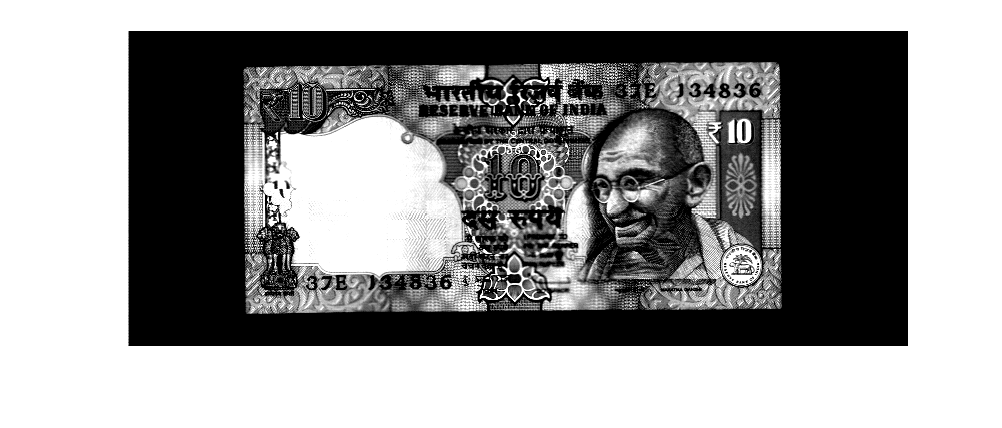

figure; imshow(I1, [50 100]); % the second param is [low high], all values lower than low are displayed as black, all values higher than 100 are displayed as white

display(min(min(I)));

    4



display(max(max(I)));

  255



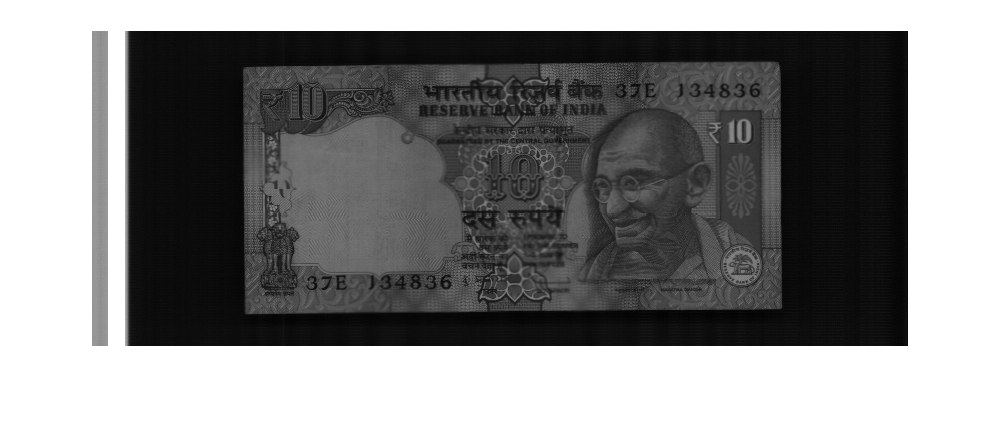

figure; imshow(I,[]); % display the min of image as back and max of image as white - in our case, there is not much difference, because the min and max of the image are close to the absolute min and max

imfinfo 'image.tif'

ans =                      Filename: 'd:\MATLAB\ImageProcessing\image.tif'
                  FileModDate: '21-Apr-2016 14:59:19'
                     FileSize: 253024
                       Format: 'tif'
                FormatVersion: []
                        Width: 816
                       Height: 315
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 7891 15778 23648 31686 39728 47798 55844 63876 71916 79971 88017 96075 104125 112158 120197 128248 136291 144344 152386 160431 168491 176529 184573 192613 200667 208722 216767 224831 232768 240718 248618]
              SamplesPerPixel: 1
                 RowsPerStrip: 10
              StripByteCounts: [7883 7887 7870 8038 8042 8070 8046

K= imfinfo('image.tif');
K.FileSize

ans = 253024

## Converting image

the IPT (image processing toolbox) has functions to conver between the image types and perform the necessary scaling.

im2uint8

mat2gray

im2double

A = [ 0.1, 0.2 0.5; -1 -2 -3.4 ; 4 5 6; 4 5 6];
A1 = im2uint8(A) % all values >1 are set to 255, all values < 0 are set to 0; all other values are multiplied by 255

A1 =    26   51  128
    0    0    0
  255  255  255
  255  255  255


AG = mat2gray(A) % scales values in A to [0,1]; the max of A becomes 1.0, the min of A becomes 0

AG =     0.3723    0.3830    0.4149
    0.2553    0.1489         0
    0.7872    0.8936    1.0000
    0.7872    0.8936    1.0000


AG2=mat2gray(A,[-2 2]) % we specify here that anything < -2 shall be 0, and anything > 2 shall be 1

AG2 =     0.5250    0.5500    0.6250
    0.2500         0         0
    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000


B_uint8 = uint8([ 0 128 255]);
B1 = im2double(B_uint8) % divides each element by 255 all uint8 elements. Note that it does not do anything, if the elements of the matrix are allready doubles

B1 =          0    0.5020    1.0000


B_uint16 = uint16([ 0 128 255]);
B2 = im2double(B_uint16) % since the elements are uint16, the division is by 2^16 (64k)

B2 =          0    0.0020    0.0039


A

A =     0.1000    0.2000    0.5000
   -1.0000   -2.0000   -3.4000
    4.0000    5.0000    6.0000
    4.0000    5.0000    6.0000


BW1 = im2bw(A) % binarization via thresholding at 0.5

BW1 =      0     0     0
     0     0     0
     1     1     1
     1     1     1


BW2 = im2bw(A, 0.2) % threshold has to be between 0 and 1

BW2 =      0     0     1
     0     0     0
     1     1     1
     1     1     1


whos BW2 % note that the output is LOGICAL

  Name      Size            Bytes  Class      Attributes

  BW2       4x3                12  logical              



## Image arithmetic functions

there are IPT functions for image arithmetic. It is unclear what is the advantage of them. According to the DIPSUM it is that they can be used directly with uint8 etc images, whereas direct use of MATAB operators requires use of doubles. However, as shown below, I can use directly the matlab operators.

imshow(I.*I)

ans =   255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255
  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255
  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255
  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255  255 